# Naïve Bayes Analysis Part 1

In this script Matlab's naive Bayes implementation and automated hyperparameter optimization search [1] is used to:

- Find out if dataset normalisation performs better.

- Find which distribution name is better (normal or kernel?).

- Find the optimal range of kernel smoothing widths.

- Investigate the prior distributions created by default compared to calculating them from the training dataset.

- Compare the performance of the dataset with all features vs the dataset with features removed

## Initial Analysis from a Naïve Bayes perspective dataset NOT normalised


clear
clc
clf
close all
% loads the letter dataset 
load letterDatasetClass.mat

letterDataset = letterDatasetNotNormalised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);
% get a default class
nBayes = NBayesClass.getDefaultInstance(letterDataset);
nBayes.nBayesModel.Prior

ans =     0.0391    0.0381    0.0381    0.0399    0.0384    0.0378    0.0393    0.0361    0.0379    0.0361    0.0367    0.0384    0.0396    0.0383    0.0382    0.0407    0.0386    0.0375    0.0381    0.0413    0.0404    0.0393    0.0377    0.0387    0.0394    0.0366


[dfltLTrainLoss, dfltTestLoss] = nBayes.getModelLoss();
nBayes.setPriorDistributionEmpirical();
nBayes.nBayesModel.Prior

ans =     0.0413    0.0379    0.0399    0.0383    0.0393    0.0391    0.0396    0.0387    0.0382    0.0375    0.0381    0.0361    0.0381    0.0361    0.0384    0.0381    0.0384    0.0394    0.0386    0.0407    0.0393    0.0377    0.0404    0.0378    0.0366    0.0368


**Compare the model between using the default prior distribution, or an empirical one calculated from the training dataset.**

[empTrainLoss, emptTestLoss] = nBayes.getModelLoss();
fprintf("Default Training Loss:   %0.04f Test Loss %0.04f\n", dfltLTrainLoss, dfltTestLoss);

Default Training Loss:   0.3539 Test Loss 0.3668


fprintf("Empirical Training Loss: %0.04f Test Loss %0.04f\n", empTrainLoss, emptTestLoss);

Empirical Training Loss: 0.3549 Test Loss 0.3678


**Setting the prior distribution to an empirical distribution:**

- **Does not affect the  model loss.**

- **Ensures that the initial prior distribution used is known.**

By default, MATLAB initialised the classifiers that have been setup for each attribute. There are 16 of them, each one configurable.

disp(nBayes.nBayesModel.DistributionNames(:,:));

  Columns 1 through 7

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  Columns 8 through 14

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  Columns 15 through 16

    {'normal'}    {'normal'}



**The performance is noted for later analysis:**

disp(nBayes);

#### Perform MATLAB's hyperparameter search (takes time)

letterDataset = letterDatasetNotNormalised;

  NBayesClass with properties:

             randomSeed: 300
    defaultRandomStream: [1×1 RandStream]
     nBayesRandomStream: [1×1 RandStream]
                  debug: 0
                dataset: [1×1 LetterDatasetClass]
            nBayesModel: [1×1 ClassificationNaiveBayes]
                      x: [16000×16 table]
                      y: [16000×1 table]
                     xt: [4000×16 table]
                     yt: [4000×1 table]
       distNamesDefault: {1×16 cell}
        distNamesKernel: {1×16 cell}
              smoothBox: {1×16 cell}
     smoothEpanechnikov: {1×16 cell}
           smoothNormal: {1×16 cell}
         smoothTriangle: {1×16 cell}
          smoothUnsused: {1×16 cell}



|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33776 |      70.386 |     0.33776 |     0.33776 |       kernel |        1.287 |


|    2 | Accept |     0.35793 |     0.55506 |     0.33776 |     0.34745 |       normal |            - |


|    3 | Accept |     0.35793 |     0.47915 |     0.33776 |     0.33776 |       normal |            - |


|    4 | Accept |     0.51687 |      67.444 |     0.33776 |     0.33777 |       kernel |       8.6162 |


|    5 | Best   |     0.24992 |       42.19 |     0.24992 |     0.24993 |       kernel |      0.30805 |


|    6 | Best   |     0.24938 |      41.653 |     0.24938 |     0.24934 |       kernel |      0.25009 |


|    7 | Accept |     0.24938 |      41.584 |     0.24938 |     0.24936 |       kernel |      0.25013 |


|    8 | Accept |     0.24971 |      42.012 |     0.24938 |      0.2494 |       kernel |      0.27016 |


|    9 | Accept |     0.24938 |      41.501 |     0.24938 |     0.24939 |       kernel |      0.25017 |


|   10 | Accept |     0.24971 |      41.652 |     0.24938 |     0.24946 |       kernel |      0.26968 |


|   11 | Accept |     0.24938 |      41.604 |     0.24938 |     0.24945 |       kernel |      0.25021 |


|   12 | Accept |     0.63389 |      71.306 |     0.24938 |     0.24947 |       kernel |       14.999 |


|   13 | Accept |     0.25828 |      41.741 |     0.24938 |     0.24947 |       kernel |      0.45363 |


|   14 | Accept |     0.24964 |      42.349 |     0.24938 |     0.24949 |       kernel |      0.28095 |


|   15 | Accept |     0.44594 |      73.655 |     0.24938 |     0.24949 |       kernel |        3.114 |


|   16 | Accept |     0.28749 |      62.268 |     0.24938 |      0.2495 |       kernel |      0.76843 |


|   17 | Accept |      0.4862 |      73.353 |     0.24938 |      0.2495 |       kernel |       5.0671 |


|   18 | Accept |     0.26841 |      53.326 |     0.24938 |     0.24949 |       kernel |      0.58156 |


|   19 | Accept |     0.39126 |       72.93 |     0.24938 |     0.24949 |       kernel |       1.9163 |


|   20 | Accept |     0.25278 |      42.072 |     0.24938 |     0.24949 |       kernel |      0.37164 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25073 |      41.785 |     0.24938 |     0.24948 |       kernel |      0.33456 |


|   22 | Accept |     0.30923 |       61.46 |     0.24938 |     0.24948 |       kernel |      0.97527 |


|   23 | Accept |     0.24995 |      42.166 |     0.24938 |     0.24951 |       kernel |      0.29221 |


|   24 | Accept |     0.24951 |       42.23 |     0.24938 |     0.24946 |       kernel |      0.25874 |


|   25 | Accept |     0.24951 |      41.852 |     0.24938 |     0.24947 |       kernel |      0.25768 |


|   26 | Accept |     0.24938 |      43.196 |     0.24938 |     0.24946 |       kernel |      0.25002 |


|   27 | Accept |     0.25474 |      42.076 |     0.24938 |     0.24946 |       kernel |      0.40781 |


|   28 | Accept |      0.5606 |      69.328 |     0.24938 |     0.24946 |       kernel |       11.666 |


|   29 | Accept |     0.42189 |      72.817 |     0.24938 |     0.24946 |       kernel |        2.444 |


|   30 | Accept |     0.24951 |      41.554 |     0.24938 |     0.24947 |       kernel |       0.2574 |


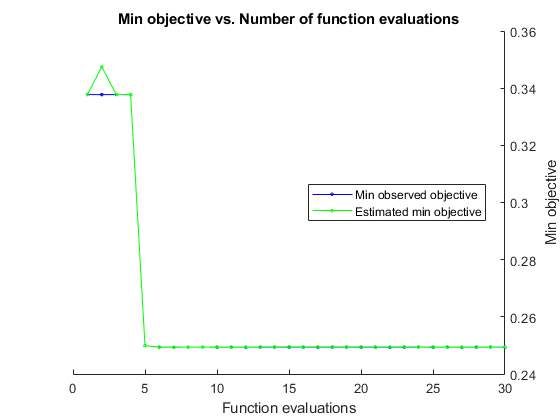

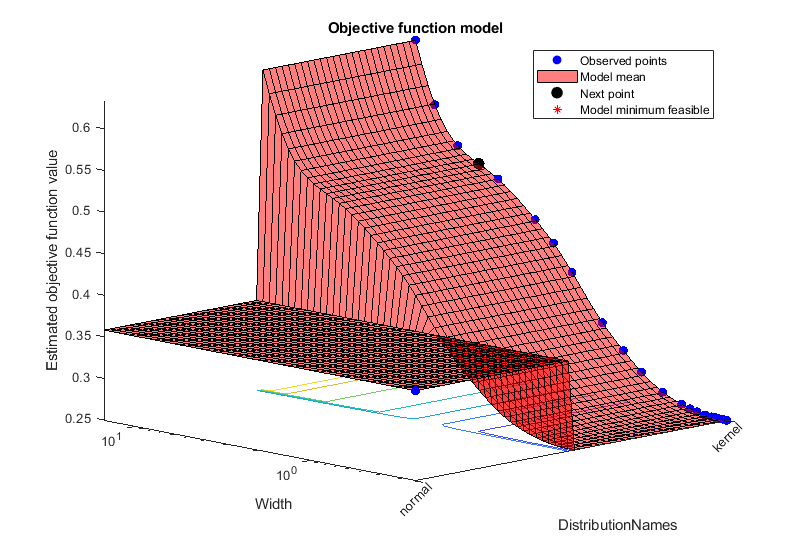


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1491.4573 seconds
Total objective function evaluation time: 1462.526

Best observed feasible point:
    DistributionNames     Width 
    _________________    _______

         kernel          0.25009

Observed objective function value = 0.24938
Estimated objective function value = 0.24945
Function evaluation time = 41.6533

Best estimated feasible point (according to models):
    DistributionNames     Width 
    _________________    _______

         kernel          0.25768

Estimated objective function value = 0.24947
Estimated function evaluation time = 41.8492



[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);
nBayes = NBayesClass.getDefaultInstance(letterDataset);
nBayes.setPriorDistributionEmpirical();
% start timer
startTime = cputime;
nBayes.fitMatlabHyperparameterOptimization();
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;

fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", ...
  trainingLoss, testLoss, nBayes.dataset.isNormalised);
fprintf("Total cpu time (seconds, includes optimization search): %02.04f", totalTime);
disp(nBayes);

Training loss: 0.2342 Test loss: 0.2508, normalised dataset: 0


## Normalised Dataset

clear

Total cpu time (seconds, includes optimization search): 6936.7188

  NBayesClass with properties:

             randomSeed: 300
    defaultRandomStream: [1×1 RandStream]
     nBayesRandomStream: [1×1 RandStream]
                  debug: 0
                dataset: [1×1 LetterDatasetClass]
            nBayesModel: [1×1 ClassificationNaiveBayes]
                      x: [16000×16 table]
                      y: [16000×1 table]
                     xt: [4000×16 table]
                     yt: [4000×1 table]
       distNamesDefault: {1×16 cell}
        distNamesKernel: {1×16 cell}
              smoothBox: {1×16 cell}
     smoothEpanechnikov: {1×16 cell}
           smoothNormal: {1×16 cell}
         smoothTriangle: {1×16 cell}
          smoothUnsused: {1×16 cell}



|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33776 |      70.235 |     0.33776 |     0.33776 |       kernel |        1.287 |


|    2 | Accept |     0.35793 |     0.43173 |     0.33776 |     0.34745 |       normal |            - |


|    3 | Accept |     0.35793 |     0.40866 |     0.33776 |     0.33776 |       normal |            - |


|    4 | Accept |     0.51687 |      70.463 |     0.33776 |     0.33777 |       kernel |       8.6162 |


|    5 | Best   |     0.24992 |      42.714 |     0.24992 |     0.24993 |       kernel |      0.30805 |


|    6 | Best   |     0.24938 |      42.589 |     0.24938 |     0.24934 |       kernel |      0.25009 |


|    7 | Accept |     0.24938 |      42.819 |     0.24938 |     0.24936 |       kernel |      0.25013 |


|    8 | Accept |     0.24971 |      42.548 |     0.24938 |      0.2494 |       kernel |      0.27016 |


|    9 | Accept |     0.24938 |      42.525 |     0.24938 |     0.24939 |       kernel |      0.25017 |


|   10 | Accept |     0.24971 |      42.683 |     0.24938 |     0.24946 |       kernel |      0.26968 |


|   11 | Accept |     0.24938 |      42.623 |     0.24938 |     0.24945 |       kernel |      0.25021 |


|   12 | Accept |     0.63389 |      71.819 |     0.24938 |     0.24947 |       kernel |       14.999 |


|   13 | Accept |     0.25828 |      43.199 |     0.24938 |     0.24947 |       kernel |      0.45363 |


|   14 | Accept |     0.24964 |      43.288 |     0.24938 |     0.24949 |       kernel |      0.28095 |


|   15 | Accept |     0.44594 |      75.309 |     0.24938 |     0.24949 |       kernel |        3.114 |


|   16 | Accept |     0.28749 |      63.464 |     0.24938 |      0.2495 |       kernel |      0.76843 |


|   17 | Accept |      0.4862 |      74.772 |     0.24938 |      0.2495 |       kernel |       5.0671 |


|   18 | Accept |     0.26841 |      55.036 |     0.24938 |     0.24949 |       kernel |      0.58156 |


|   19 | Accept |     0.39126 |      75.089 |     0.24938 |     0.24949 |       kernel |       1.9163 |


|   20 | Accept |     0.25278 |      42.841 |     0.24938 |     0.24949 |       kernel |      0.37164 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25073 |       43.76 |     0.24938 |     0.24948 |       kernel |      0.33456 |


|   22 | Accept |     0.30923 |      62.688 |     0.24938 |     0.24948 |       kernel |      0.97527 |


|   23 | Accept |     0.24995 |      41.853 |     0.24938 |     0.24951 |       kernel |      0.29221 |


|   24 | Accept |     0.24951 |      41.731 |     0.24938 |     0.24946 |       kernel |      0.25874 |


|   25 | Accept |     0.24951 |      41.712 |     0.24938 |     0.24947 |       kernel |      0.25768 |


|   26 | Accept |     0.24938 |      41.631 |     0.24938 |     0.24946 |       kernel |      0.25002 |


|   27 | Accept |     0.25474 |      41.745 |     0.24938 |     0.24946 |       kernel |      0.40781 |


|   28 | Accept |      0.5606 |      72.456 |     0.24938 |     0.24946 |       kernel |       11.666 |


|   29 | Accept |     0.42189 |      73.849 |     0.24938 |     0.24946 |       kernel |        2.444 |


|   30 | Accept |     0.24951 |      42.153 |     0.24938 |     0.24947 |       kernel |       0.2574 |



__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1511.2644 seconds
Total objective function evaluation time: 1488.434

Best observed feasible point:
    DistributionNames     Width 
    _________________    _______

         kernel          0.25009

Observed objective function value = 0.24938
Estimated objective function value = 0.24945
Function evaluation time = 42.5888

Best estimated feasible point (according to models):
    DistributionNames     Width 
    _________________    _______

         kernel          0.25768

Estimated objective function value = 0.24947
Estimated function evaluation time = 42.3156



Training loss: 0.2342 Test loss: 0.2508, normalised dataset: 0


Total cpu time (seconds, includes optimization search): 7227.4375

  NBayesClass with properties:

             randomSeed: 300
    defaultRandomStream: [1×1 RandStream]
     nBayesRandomStream: [1×1 RandStream]
                  debug: 0
                dataset: [1×1 LetterDatasetClass]
            nBayesModel: [1×1 ClassificationNaiveBayes]
                      x: [16000×16 table]
                      y: [16000×1 table]
                     xt: [4000×16 table]
                     yt: [4000×1 table]
       distNamesDefault: {1×16 cell}
        distNamesKernel: {1×16 cell}
              smoothBox: {1×16 cell}
     smoothEpanechnikov: {1×16 cell}
           smoothNormal: {1×16 cell}
         smoothTriangle: {1×16 cell}
          smoothUnsused: {1×16 cell}



clc

clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetNormalised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);

% get a kernel class
nBayes = NBayesClass.getDefaultInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();
% start timer
startTime = cputime;
predictions = resubPredict(model);
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;

fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isNormalised);
fprintf("Total cpu time (seconds): %02.04f", totalTime);
disp(nBayes);

#### Optimization (MATLAB sets distribution to Kernel, normal (gaussian)

letterDataset = letterDatasetNormalised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);

Training loss: 0.3549 Test loss: 0.3678, normalised dataset: 1


X = table2array(X);

Total cpu time (seconds): 0.7188

Y = table2array(Y);

  NBayesClass with properties:

             randomSeed: 300
    defaultRandomStream: [1×1 RandStream]
     nBayesRandomStream: [1×1 RandStream]
                  debug: 0
                dataset: [1×1 LetterDatasetClass]
            nBayesModel: [1×1 ClassificationNaiveBayes]
                      x: [16000×16 table]
                      y: [16000×1 table]
                     xt: [4000×16 table]
                     yt: [4000×1 table]
       distNamesDefault: {1×16 cell}
        distNamesKernel: {1×16 cell}
              smoothBox: {1×16 cell}
     smoothEpanechnikov: {1×16 cell}
           smoothNormal: {1×16 cell}
         smoothTriangle: {1×16 cell}
          smoothUnsused: {1×16 cell}



nBayes = NBayesClass(letterDataset);
% start timer
startTime = cputime
nBayes.fitMatlabHyperparameterOptimization();
predictions = resubPredict(nBayes.nBayesModel);
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;
fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", ...

startTime = 1.4394e+04

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33501 |      67.211 |     0.33501 |     0.33501 |       kernel |       0.5295 |


|    2 | Accept |     0.35793 |      0.4106 |     0.33501 |     0.34603 |       normal |            - |


|    3 | Accept |     0.35793 |     0.40112 |     0.33501 |     0.33501 |       normal |            - |


|    4 | Accept |     0.54537 |      67.304 |     0.33501 |     0.33502 |       kernel |       5.0418 |


|    5 | Best   |        0.25 |      26.771 |        0.25 |     0.25001 |       kernel |     0.097246 |


|    6 | Accept |     0.25531 |       43.15 |        0.25 |     0.24998 |       kernel |      0.16444 |


|    7 | Best   |     0.24994 |      24.642 |     0.24994 |     0.24971 |       kernel |     0.075972 |


|    8 | Accept |     0.25007 |      27.823 |     0.24994 |     0.24988 |       kernel |      0.09833 |


|    9 | Accept |     0.24994 |      24.686 |     0.24994 |     0.24988 |       kernel |     0.075985 |


|   10 | Accept |        0.25 |      24.699 |     0.24994 |     0.24988 |       kernel |     0.092734 |


|   11 | Accept |        0.25 |      25.349 |     0.24994 |      0.2499 |       kernel |     0.089785 |


|   12 | Accept |     0.24994 |      25.243 |     0.24994 |     0.24989 |       kernel |     0.075988 |


|   13 | Accept |     0.78637 |      67.686 |     0.24994 |     0.24998 |       kernel |       9.7236 |


|   14 | Accept |       0.464 |      74.766 |     0.24994 |     0.24995 |       kernel |       1.5011 |


|   15 | Accept |     0.27132 |      52.328 |     0.24994 |     0.24995 |       kernel |      0.25841 |


|   16 | Accept |     0.25033 |      35.827 |     0.24994 |     0.24997 |       kernel |      0.12027 |


|   17 | Accept |     0.24994 |      24.709 |     0.24994 |     0.24997 |       kernel |     0.084018 |


|   18 | Accept |     0.25019 |      32.192 |     0.24994 |     0.24997 |       kernel |       0.1097 |


|   19 | Accept |     0.24994 |      24.689 |     0.24994 |     0.24998 |       kernel |     0.075967 |


|   20 | Accept |     0.24994 |      24.827 |     0.24994 |     0.24998 |       kernel |     0.084334 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.50222 |      71.238 |     0.24994 |     0.24998 |       kernel |       2.7119 |


|   22 | Accept |     0.39413 |      74.873 |     0.24994 |     0.24997 |       kernel |       0.8542 |


|   23 | Accept |     0.29552 |      60.232 |     0.24994 |     0.24994 |       kernel |      0.35897 |


|   24 | Accept |     0.26091 |      45.144 |     0.24994 |     0.24994 |       kernel |      0.20397 |


|   25 | Accept |     0.25158 |      39.315 |     0.24994 |     0.24995 |       kernel |      0.14035 |


|   26 | Accept |     0.25096 |      37.597 |     0.24994 |     0.24995 |       kernel |      0.12933 |


|   27 | Accept |     0.24994 |      24.445 |     0.24994 |     0.24994 |       kernel |     0.079584 |


|   28 | Accept |     0.25014 |      28.548 |     0.24994 |     0.24994 |       kernel |      0.10389 |


|   29 | Accept |     0.63839 |      69.663 |     0.24994 |     0.24994 |       kernel |       7.0072 |


|   30 | Accept |     0.25026 |       33.92 |     0.24994 |     0.24994 |       kernel |      0.11443 |


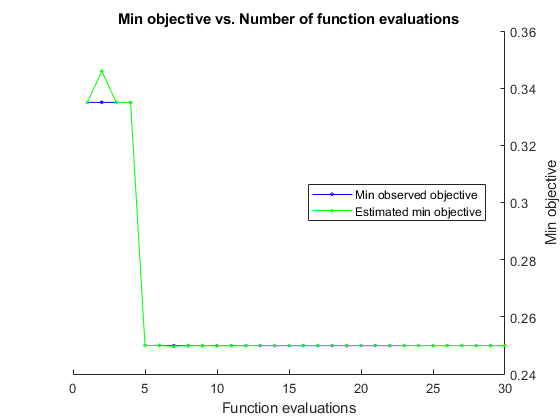

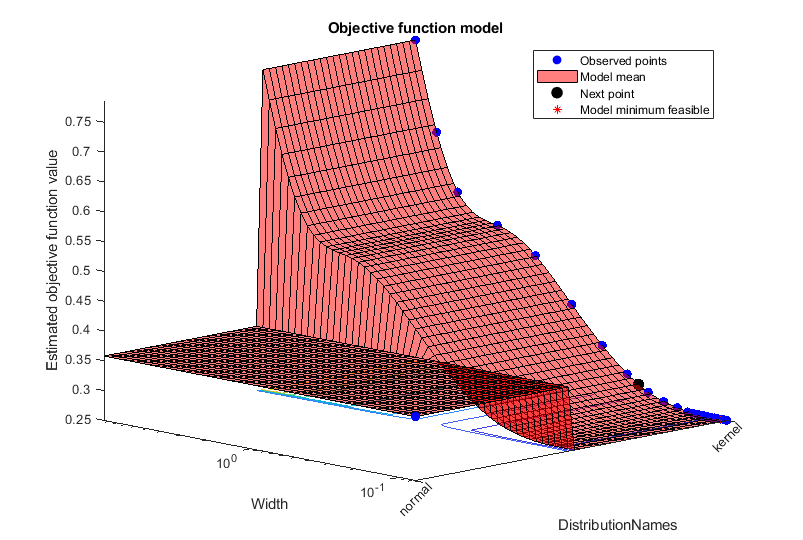


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1201.0278 seconds
Total objective function evaluation time: 1179.6901

Best observed feasible point:
    DistributionNames     Width  
    _________________    ________

         kernel          0.075972

Observed objective function value = 0.24994
Estimated objective function value = 0.24996
Function evaluation time = 24.6423

Best estimated feasible point (according to models):
    DistributionNames     Width  
    _________________    ________

         kernel          0.079584

Estimated objective function value = 0.24994
Estimated function evaluation time = 24.611



  trainingLoss, testLoss, nBayes.dataset.isNormalised);

fprintf("Total cpu time (seconds, includes optimization search): %02.04f", totalTime);
disp(nBayes);

### 'kernel' distribution on Normalised dataset

clear
clc
clf
close all

Training loss: 0.2338 Test loss: 0.2520, normalised dataset: 1


% loads the letter dataset 

Total cpu time (seconds, includes optimization search): 4842.4531

% 

  NBayesClass with properties:

             randomSeed: 300
    defaultRandomStream: [1×1 RandStream]
     nBayesRandomStream: [1×1 RandStream]
                  debug: 0
                dataset: [1×1 LetterDatasetClass]
            nBayesModel: [1×1 ClassificationNaiveBayes]
                      x: [16000×16 table]
                      y: [16000×1 table]
                     xt: [4000×16 table]
                     yt: [4000×1 table]
       distNamesDefault: {1×16 cell}
        distNamesKernel: {1×16 cell}
              smoothBox: {1×16 cell}
     smoothEpanechnikov: {1×16 cell}
           smoothNormal: {1×16 cell}
         smoothTriangle: {1×16 cell}
          smoothUnsused: {1×16 cell}



load letterDatasetClass.mat
letterDataset = letterDatasetNormalised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);

% get a kernel class
nBayes = NBayesClass.getKernelInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();
startTime = cputime;
predictions = resubPredict(model);
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;
fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isNormalised);
fprintf("Total cpu time (seconds): %02.04f", totalTime);
disp(nBayes);

## Reduced Attribute Standardised Dataset Test Run

A final normalised, kernel run is performed on the **dataset with the highly correlated features removed.**

clear
clc
clf
close all
% loads the letter dataset 
% 

Training loss: 0.3040 Test loss: 0.3213, normalised dataset: 1


load letterDatasetClass.mat

Total cpu time (seconds): 588.8594

letterDataset = letterDatasetNormalisedReducedFeatures

  NBayesClass with properties:

             randomSeed: 300
    defaultRandomStream: [1×1 RandStream]
     nBayesRandomStream: [1×1 RandStream]
                  debug: 0
                dataset: [1×1 LetterDatasetClass]
            nBayesModel: [1×1 ClassificationNaiveBayes]
                      x: [16000×16 table]
                      y: [16000×1 table]
                     xt: [4000×16 table]
                     yt: [4000×1 table]
       distNamesDefault: {1×16 cell}
        distNamesKernel: {1×16 cell}
              smoothBox: {1×16 cell}
     smoothEpanechnikov: {1×16 cell}
           smoothNormal: {1×16 cell}
         smoothTriangle: {1×16 cell}
          smoothUnsused: {1×16 cell}



[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);

% get a kernel class
nBayes = NBayesClass.getKernelInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();
startTime = cputime;
predictions = resubPredict(model);
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;

letterDataset =   LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {'onPixelCount'  'xBar'  'yBar'  'x2Bar'  'y2Bar'  'xyBar'  'x2yBr'  'xy2Br'  'xEge'  'xEgvy'  'yEge'  'yEgvx'}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
              isNormalised: 1
          isRemovedFeature: 1


fprintf("Training loss: %0.04f Test loss: %0.04f, selected features, normalised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isNormalised);
fprintf("Total cpu time (seconds): %02.04f", totalTime);
disp(nBayes);

#### Optimization (uses letterDataset defined in previous cell)

nBayes = NBayesClass.getKernelInstance(letterDataset);
startTime = cputime;
nBayes.fitMatlabHyperparameterOptimization();
predictions = resubPredict(nBayes.nBayesModel);
[trainingLoss, testLoss] = nBayes.getModelLoss();
endTime = cputime;
totalTime = endTime - startTime;
fprintf("Training loss: %0.04f Test loss: %0.04f, selected features, normalised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isNormalised);

Training loss: 0.3059 Test loss: 0.3123, selected features, normalised dataset: 1


fprintf("Total cpu time (seconds, includes optimization search): %02.04f", totalTime);

Total cpu time (seconds): 427.7500

disp(nBayes);

  NBayesClass with properties:

             randomSeed: 300
    defaultRandomStream: [1×1 RandStream]
     nBayesRandomStream: [1×1 RandStream]
                  debug: 0
                dataset: [1×1 LetterDatasetClass]
            nBayesModel: [1×1 ClassificationNaiveBayes]
                      x: [16000×12 table]
                      y: [16000×1 table]
                     xt: [4000×12 table]
                     yt: [4000×1 table]
       distNamesDefault: {1×12 cell}
        distNamesKernel: {1×12 cell}
              smoothBox: {1×12 cell}
     smoothEpanechnikov: {1×12 cell}
           smoothNormal: {1×12 cell}
         smoothTriangle: {1×12 cell}
          smoothUnsused: {1×16 cell}



## Results Conclusion

The results from all the tests are below:

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33719 |      50.622 |     0.33719 |     0.33719 |       kernel |      0.59875 |


|    2 | Accept |     0.34912 |     0.38473 |     0.33719 |     0.34292 |       normal |            - |


|    3 | Accept |     0.34912 |     0.36906 |     0.33719 |     0.33719 |       normal |            - |


|    4 | Accept |     0.52983 |      52.772 |     0.33719 |      0.3372 |       kernel |       5.1836 |


|    5 | Best   |     0.24797 |      19.359 |     0.24797 |     0.24798 |       kernel |       0.0932 |


|    6 | Accept |     0.24797 |      19.274 |     0.24797 |     0.24797 |       kernel |     0.094061 |


|    7 | Accept |     0.25189 |       30.65 |     0.24797 |     0.24793 |       kernel |      0.16072 |


|    8 | Accept |     0.24817 |      25.566 |     0.24797 |       0.248 |       kernel |      0.11358 |


|    9 | Accept |     0.24811 |      25.734 |     0.24797 |     0.24793 |       kernel |      0.10824 |


|   10 | Accept |     0.24816 |      23.446 |     0.24797 |     0.24797 |       kernel |      0.10635 |


|   11 | Accept |     0.24797 |      19.351 |     0.24797 |     0.24797 |       kernel |     0.093284 |


|   12 | Accept |     0.78746 |      54.052 |     0.24797 |     0.24799 |       kernel |       9.7261 |


|   13 | Accept |     0.45887 |      52.126 |     0.24797 |     0.24798 |       kernel |       1.6695 |


|   14 | Accept |     0.26886 |      39.275 |     0.24797 |     0.24798 |       kernel |      0.28281 |


|   15 | Accept |     0.24905 |      28.979 |     0.24797 |     0.24798 |       kernel |      0.12827 |


|   16 | Accept |     0.24804 |      22.157 |     0.24797 |     0.24796 |       kernel |       0.1013 |


|   17 | Accept |     0.24797 |      19.171 |     0.24797 |     0.24798 |       kernel |      0.09336 |


|   18 | Accept |     0.49202 |      51.167 |     0.24797 |     0.24798 |       kernel |       2.9031 |


|   19 | Accept |     0.24797 |      22.088 |     0.24797 |     0.24796 |       kernel |      0.10116 |


|   20 | Accept |     0.24797 |      19.399 |     0.24797 |     0.24798 |       kernel |     0.093208 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.39346 |      54.496 |     0.24797 |     0.24798 |       kernel |      0.96055 |


|   22 | Accept |     0.29389 |      47.312 |     0.24797 |     0.24798 |       kernel |      0.39991 |


|   23 | Accept |     0.25739 |      35.083 |     0.24797 |     0.24798 |       kernel |        0.214 |


|   24 | Accept |     0.25437 |      31.606 |     0.24797 |     0.24798 |       kernel |      0.18488 |


|   25 | Accept |     0.25022 |       29.06 |     0.24797 |     0.24798 |       kernel |      0.14282 |


|   26 | Accept |     0.28025 |      44.049 |     0.24797 |     0.24798 |       kernel |      0.33362 |


|   27 | Accept |     0.62905 |      52.443 |     0.24797 |     0.24796 |       kernel |       7.0916 |


|   28 | Accept |     0.26141 |      38.304 |     0.24797 |     0.24796 |       kernel |      0.24318 |


|   29 | Accept |     0.24836 |      26.632 |     0.24797 |     0.24795 |       kernel |      0.11971 |


|   30 | Accept |     0.43002 |      54.361 |     0.24797 |     0.24795 |       kernel |        1.252 |


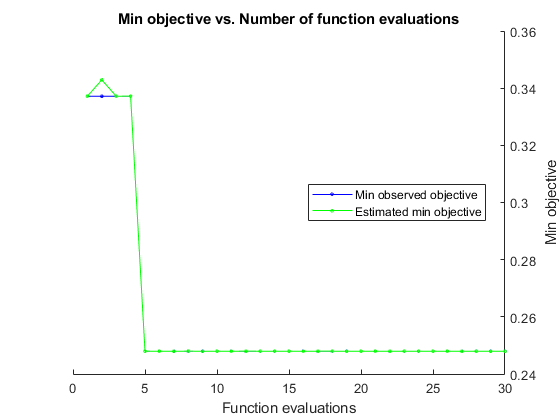

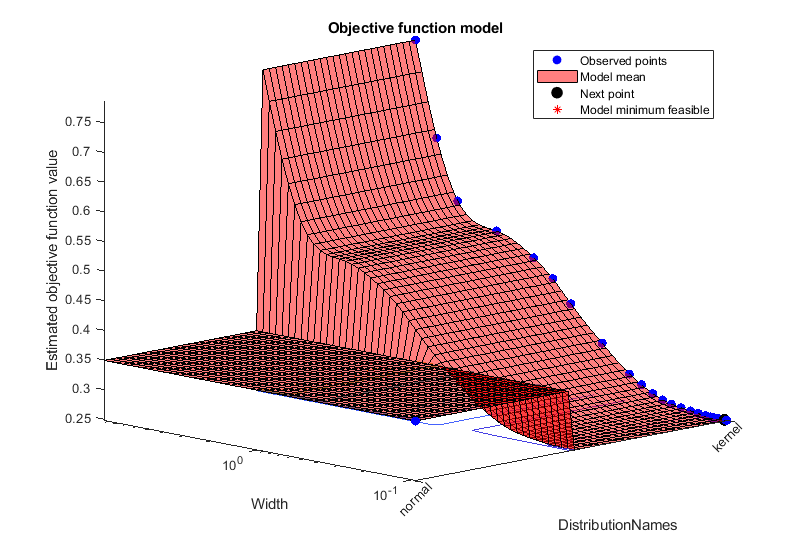


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1010.1156 seconds
Total objective function evaluation time: 989.2904

Best observed feasible point:
    DistributionNames    Width 
    _________________    ______

         kernel          0.0932

Observed objective function value = 0.24797
Estimated objective function value = 0.248
Function evaluation time = 19.3592

Best estimated feasible point (according to models):
    DistributionNames     Width 
    _________________    _______

         kernel          0.10116

Estimated objective function value = 0.24795
Estimated function evaluation time = 22.1011



Training loss: 0.2350 Test loss: 0.2502, selected features, normalised dataset: 1


Total cpu time (seconds, includes optimization search): 4585.1719

  NBayesClass with properties:

             randomSeed: 300
    defaultRandomStream: [1×1 RandStream]
     nBayesRandomStream: [1×1 RandStream]
                  debug: 0
                dataset: [1×1 LetterDatasetClass]
            nBayesModel: [1×1 ClassificationNaiveBayes]
                      x: [16000×12 table]
                      y: [16000×1 table]
                     xt: [4000×12 table]
                     yt: [4000×1 table]
       distNamesDefault: {1×12 cell}
        distNamesKernel: {1×12 cell}
              smoothBox: {1×12 cell}
     smoothEpanechnikov: {1×12 cell}
           smoothNormal: {1×12 cell}
         smoothTriangle: {1×12 cell}
          smoothUnsused: {1×16 cell}



    isDatasetNormalised    empiricalPriorDistribution    isOptimizationSearch    initialDistributionType    TrainLoss    TestLoss    kernelWidth     fewerAttributes    approxCpuTime    totalTime
    ___________________    __________________________    ____________________    _______________________    _________    ________    ____________    _______________    _____________    _________

          {'no' }                   {'no' }                    {'no' }                 {'normal'}            0.3539       0.3668     {'N/A'     }        {'no' }          {'__'  }       {'__'  } 
          {'no' }                   {'yes'}                    {'no' }    

results = readtable("nBayesParameterSearchPart1.csv", "Delimiter", ",");
disp(results);

Conclusions drawn from the full dataset:

- Normalisation of the attributes has no noticeable effect on the loss.

- The kernal distribution performance is better than the normal distribution, in terms of loss, but it takes longer.

- The hyperparameter search takes less time when the dataset has been normalised.

Conclusions drawn from using fewer features:

- Reducing the features has a very small effect on the training and test loss.

- Setting the prior distribution to the training dataset's empirical distribution has little effect compared to the default. Setting it is prefereable: the values are calculated using the training dataset, are known and can be reproduced.

- The optimization task is quickest using fewer features, on a normalised dataset.

- The normalised dataset hyperparameter value for the optimized kernel width is reported as 0.11377

Further work on the dataset should use the normalised dataset with fewer features: the only noticeable difference is in the time taken to perform the training.

Matlab displays a warning advising the standardization of numeric predictors when optimizing using the width hyperparameter. The normalised dataset, using zscore normalization, provides a noticeable reduction in the time taken to run the analysis tasks.

### References

[1] Train multiclass naive Bayes model, fitcnb. MATLAB documentation. https://www.mathworks.com/help/releases/R2020b/stats/fitcnb.html